# Display RGB/CMF 

Github Link: https://github.com/pratheepkumar1/Principles-of-Color-Science/tree/main/Assignment%205%20RGB%20CMF

#### Reading the Dataset

warning('off','all');
lms_dataset = readtable("HW_Opponency_Data.xlsx",Sheet="LMS");
rgb_spd_dataset = readtable("HW_DisplaySPD_Data.xlsx",Sheet="DisplaySPD");
cie_dataset = readtable("HW_DisplaySPD_Data.xlsx",Sheet="CIE 1931");

### Question 1: Compute the LMS values of the display’s three primaries

- Create LMS relative sensitivity matrix

- Create Spectral radiance matrix

- Find the change in wavelength

- Calculate LMS of the display using the equation

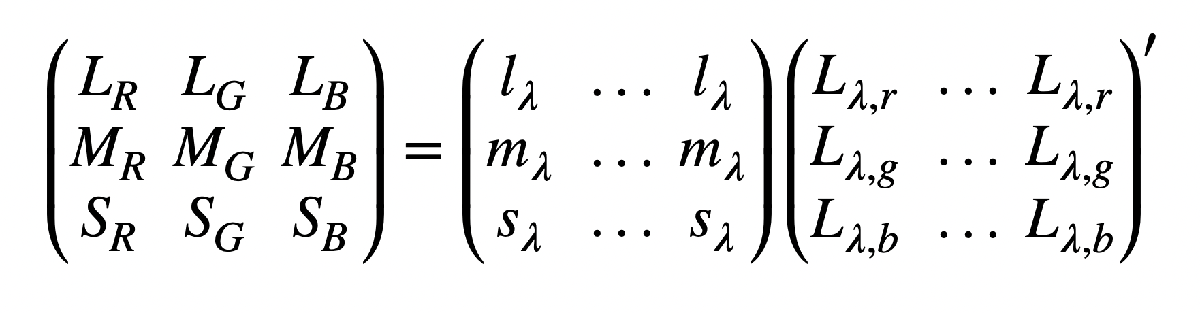

lms_matrix = transpose(lms_dataset{:,[2:4]});

rgb_spd = transpose(rgb_spd_dataset{:,[2:4]});

wavelength = lms_dataset{:,1};
d_lambda = mean(diff(wavelength));

LMS_RGB = calc_LMS_source(lms_matrix,transpose(rgb_spd),d_lambda);

*Generating Table of LMS for the Display (Only for Table Visualisation)*

Table_LMS = array2table(LMS_RGB);
Table_LMS.Properties.VariableNames(1:3) = {'L','M','S'};

### Question 1: Answer

Table_LMS

Table_LMS = 3×3 table
        L           M           S    
    _________    ________    ________

      0.15263      0.3782    0.035192
     0.048391     0.38605    0.052175
    0.0054293    0.035684     0.30713


### Question 2a: Compute the color matching functions (CMFs, also known as r-bar, g-bar, b-bar) of the display’s primaries

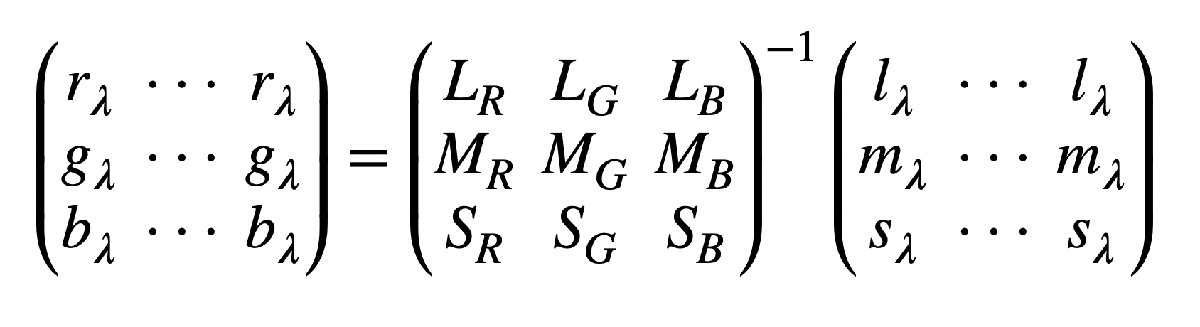

CMF_RGB = LMS_RGB\lms_matrix;
CMF_RGB_norm = custom_normalization(CMF_RGB);

*Generating Table of CMF for the Display (Only for Table Visualisation)*

CMF_RGB_norm_transpose = transpose(CMF_RGB_norm);
Table_CMF = array2table(CMF_RGB_norm_transpose);
Table_CMF.Properties.VariableNames(1:3) = {'R','G','B'};

### Question 2a: Answer

Table_CMF

Table_CMF = 36×3 table
        R              G             B    
    __________    ___________    _________

    0.00083531    -0.00072992    0.0054635
     0.0033521     -0.0029308     0.021926
      0.011629      -0.010337     0.077426
      0.029659      -0.027039       0.2048
      0.066079      -0.061632      0.47387
      0.082573      -0.080529      0.65199
      0.073871      -0.079189      0.71756
      0.040539      -0.057211      0.65201
    -0.0032548       -0.02795      0.57032
     -0.060719         0.0153      0.48825
      -0.12362       0.078536       0.3249
      -0.17989        0.14927      0.18199
      -0.24692        0.24298     0.092164
      -0.32796        0.37402     0.030114
       -0.3667        0.50612    -0.018684
      -0.31676        0.57869     -0.04347


### Question 2b: Plotting CMFs versus wavelength

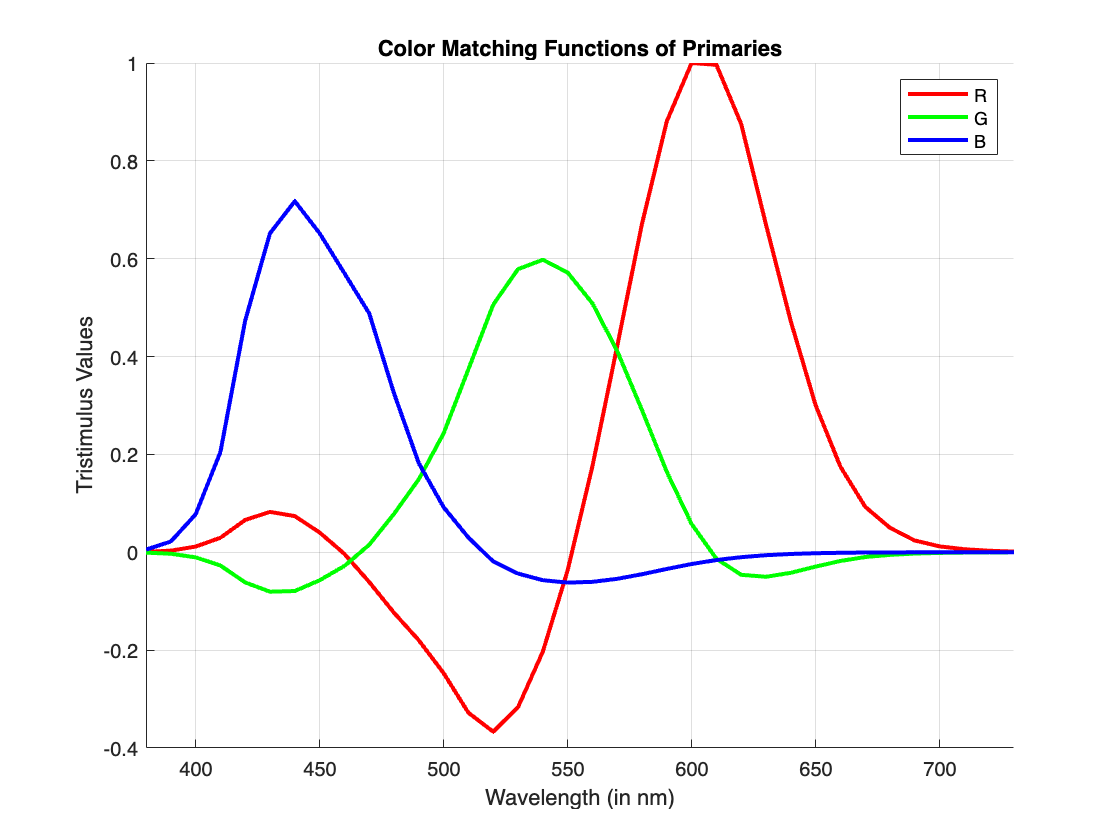

figure;
colors=['r','g','b'];
labels = ['Red','Green','Blue'];
for i = 1:3
    hold on
    plot(lms_dataset{:,1},CMF_RGB_norm_transpose(:,i), ...
        "LineWidth",2,"Color",colors(i))
end
grid on
xlabel('Wavelength (in nm)')
ylabel('Tristimulus Values')
xlim([380 730])
legend('R','G','B');
title('Color Matching Functions of Primaries')
hold off

### Question 3: Comparing the book's Fig 4.14 (p 56) to our plot (right side)      

### 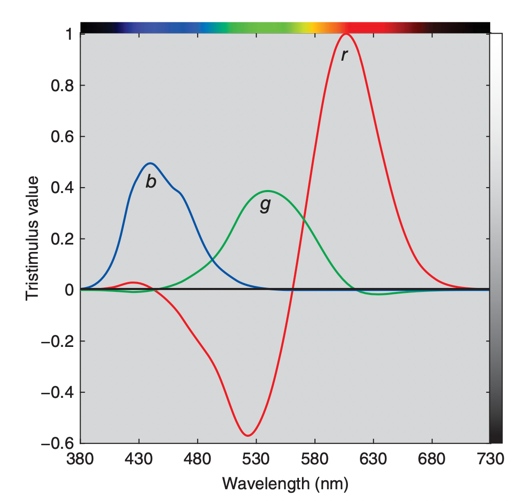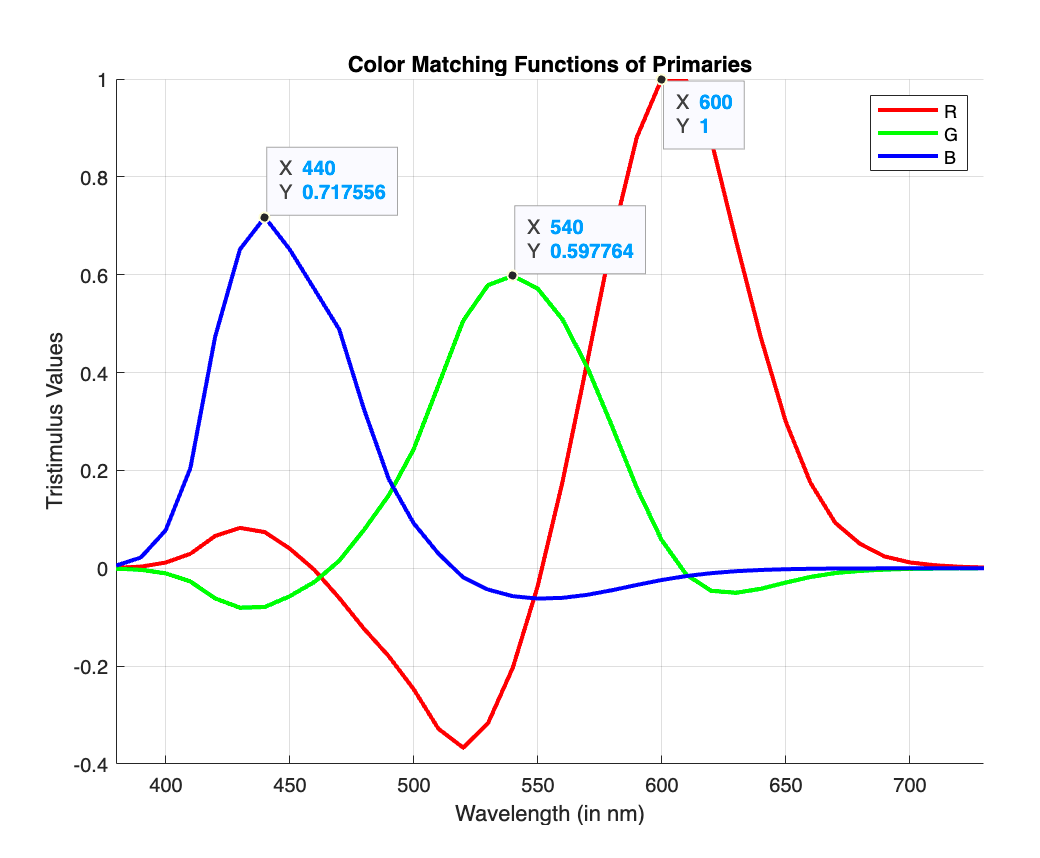

Color-matching functions of the Display primaries might result from using 440nm (blue), 540nm (green) and  600m (red). In the book's example, more amount of red is added in the fixed field for color matching and blue is almost not added in the fixed field. Whereas, in our computed plot for the display, more amount of blue light is added in the fixed field for color matching and is represented as negative value in the graph. This might be because of it's increased energy nature. Emitting more blue light enhances the visual quality of the display through increased brightness..

### Question 4: 3x3 matrix to linearly transform the computedCMFs to approximate the CIE 1931 standard colorimetric observer				

- *r𝜆*, *g**𝜆*, and *b**𝜆*, were normalized to unit area 

- Deriving *V𝜆 *from y-bar value of CIE 1931 Data source (HW_DisplaySPD_Data.xlsx)

- Computing 3x3 matrix (M_function) using the following equation Eq 4.12

            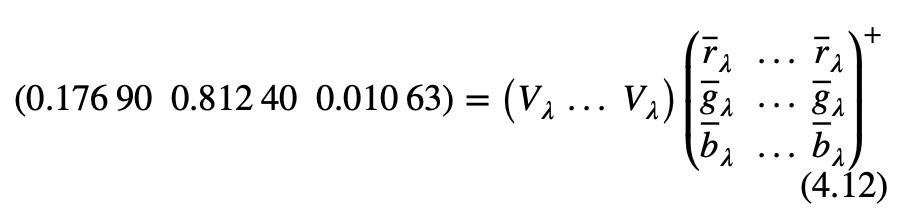

CIE_source = cie_dataset{:,2:4};

r_bar_norm = normalize(CMF_RGB(1,:),'norm',1);
g_bar_norm = normalize(CMF_RGB(2,:),'norm',1);
b_bar_norm = normalize(CMF_RGB(3,:),'norm',1);

rgb_bar_norm = [r_bar_norm;g_bar_norm;b_bar_norm];

M_function = transpose(CIE_source)*pinv(rgb_bar_norm);

### **Question 4: Answer**

M_function

M_function =     9.1919    4.4922    2.2744
    4.7800    9.1800    0.8955
    0.3086    1.4809   11.8684


### **Question 5: **Plot the computed approximation together on the same axes with the actual CIE 1931 functions

- Calculating the approximation using the equation 4.15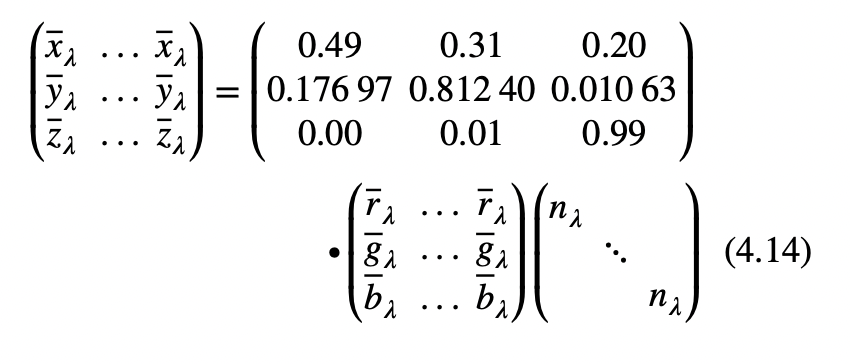 

- To fix the residual error, we are multiplying with *n**𝜆 *and* n𝜆* is calculated using equation 4.16

% Calculate xyz-bar for the displays 
xyz_bar = calc_CIE(M_function,rgb_bar_norm);
xyz_bar_norm = (custom_normalization(xyz_bar));

#### Plotting the graph for computed LCD primaries against CIE 1931 standard colorimetric observer.

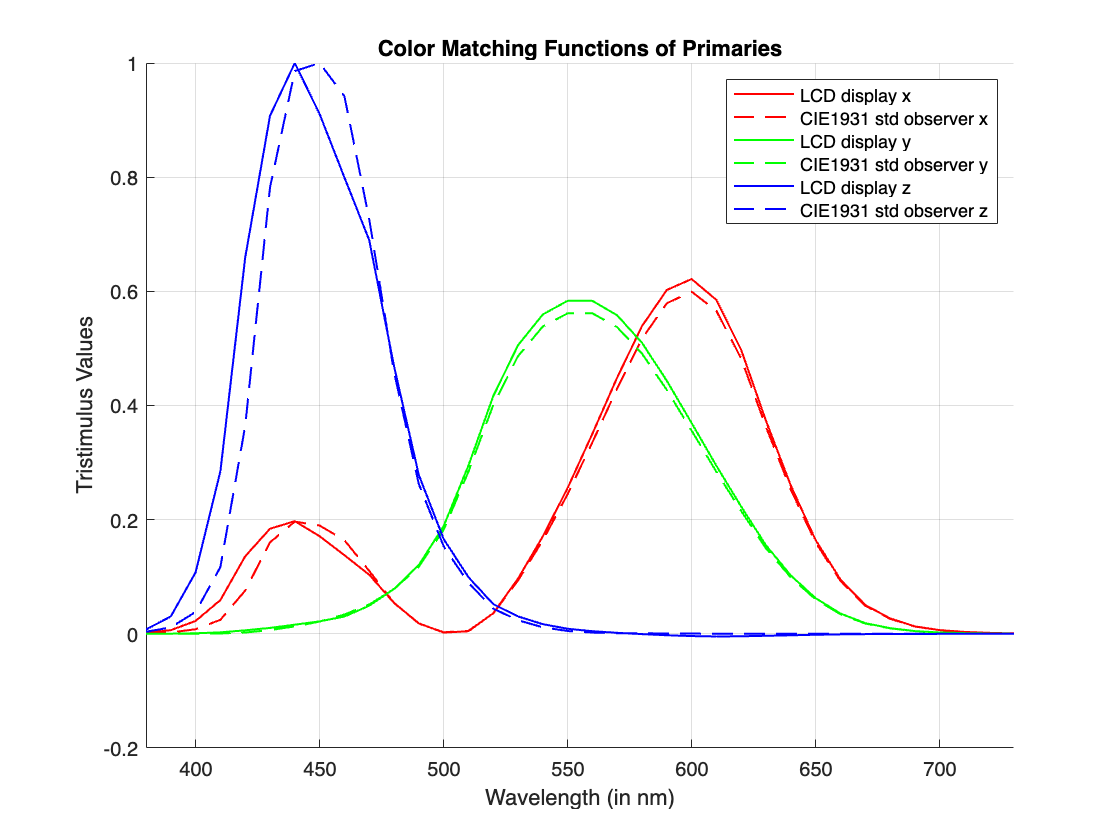

CIE_source_norm = custom_normalization(CIE_source);
xyz_bar_norm_transpose = transpose(xyz_bar_norm);

figure;
colors=['r','g','b'];
for i = 1:3
    hold on
    plot(lms_dataset{:,1},xyz_bar_norm_transpose(:,i),"LineWidth",1, ...
        "Color",colors(i));
    plot(lms_dataset{:,1},CIE_source_norm(:,i),"LineWidth",1,"Color", ...
        colors(i),"LineStyle","--");
end
grid on
xlabel('Wavelength (in nm)');
ylabel('Tristimulus Values');
xlim([lms_dataset{1,1} lms_dataset{end,1}]);
title('Color Matching Functions of Primaries');
legend('LCD display x','CIE1931 std observer x','LCD display y', ...
    'CIE1931 std observer y','LCD display z','CIE1931 std observer z');
hold off

On comparing the computed LCD primaries against CIE 1931 standard colorimetric observer, as the wavelength increase, especially after 500nm, all the primaries of LCD appears to have higher tristimulus value. So, for shorter wavelength, the the weighing used from*V𝜆* for calculating might be an issue. Similar case was found with Gibson and Tyndall (mentioned in page 62)

### Function used:

*Function to normalize a matrix with its peak value*

function n = custom_normalization(x)
    max_value = max(x, [], 'all');
    n = x/max_value;
end

*Function to calculate LMS of light source*

function T = calc_LMS_source(t,s,d_lambda)
    T = t*s*d_lambda;
end

Function to calculate the approximation of Primaries with respect to CIE 1931 Standard colorimetric observer

function CIE = calc_CIE(M,rgb_bar)
    CIE = M*rgb_bar;
end